# Import Keras Model

KerasModel = importTensorFlowNetwork('./digitsDAGnet');

Importing the saved model...
Translating the model, this may take a few minutes...
Finished translation. Assembling network...


Import finished.


### Configure model with DeepNetwork Designer

deepNetworkDesigner

### Data Preprocessing

DataPath = 'C:\Program Files\MATLAB\R2022a\toolbox\nnet\nndemos\nndatasets\DigitDataset\';
imds = imageDatastore(DataPath,'IncludeSubfolders',true,'LabelSource','foldernames');
[trainimds,testimds]  = splitEachLabel(imds,0.7);
options = trainingOptions('adam',...
    'InitialLearnRate',0.01,...
    'Verbose',0,...
    'ExecutionEnvironment','gpu',...
    'Plots','training-progress',...
    'Shuffle',"every-epoch");

### Model Training

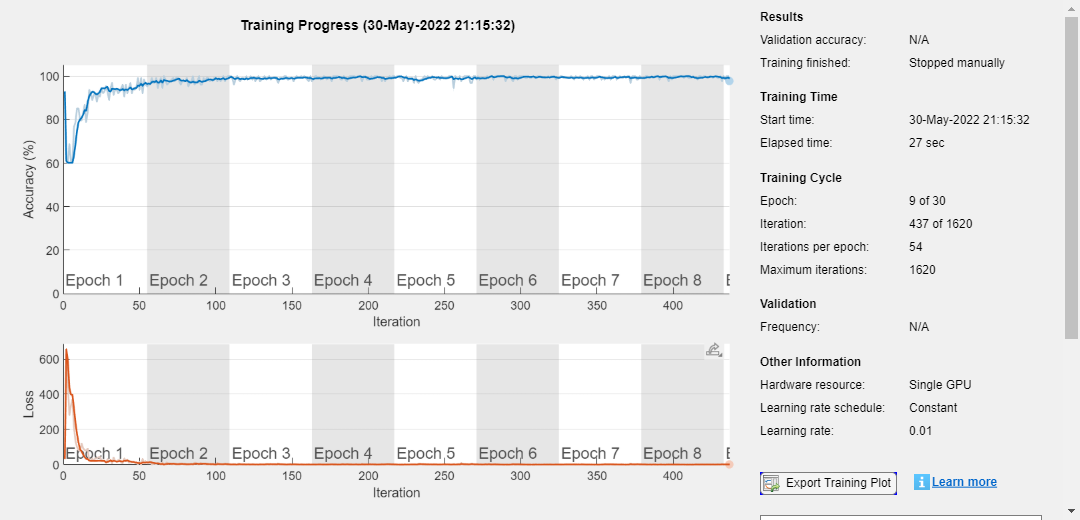

mdl = trainNetwork(trainimds,lgraph_1,options);

### Evaluate Model

YPredict = classify(mdl,testimds);
Acc = mean(testimds.Labels==YPredict)

Acc = 0.8100

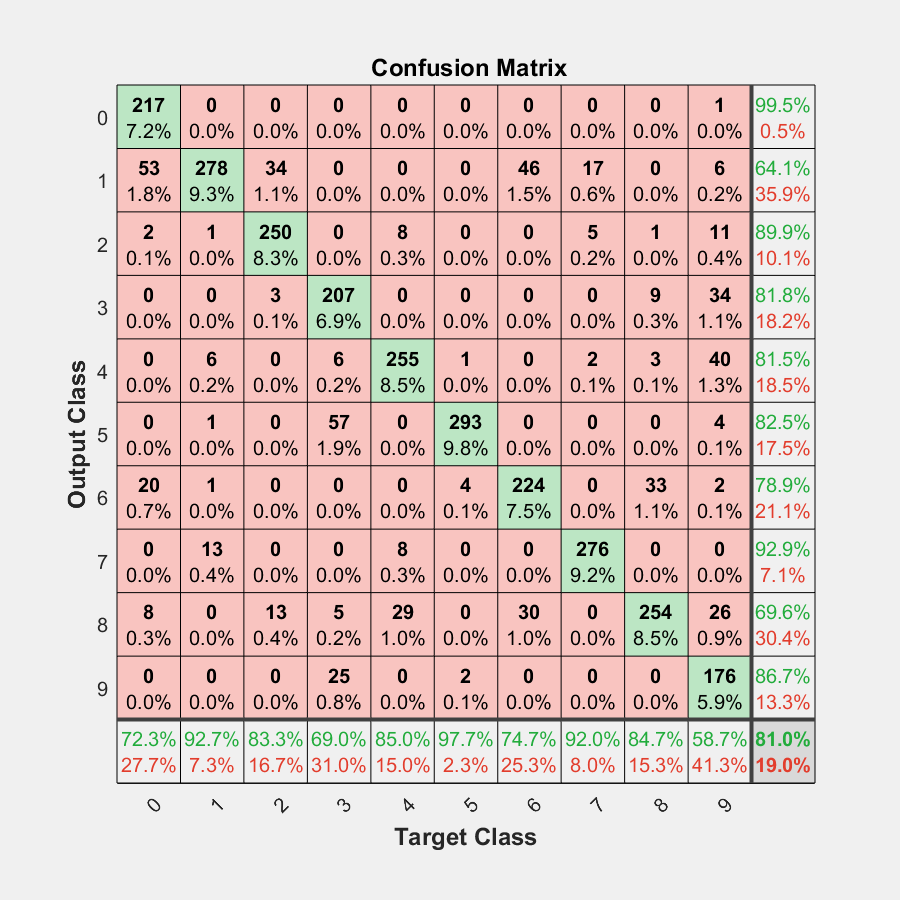

figure
plotconfusion(testimds.Labels,YPredict)